close all
clear variables
clc

opt=[];

## Domain bounds

DomainBounds.xmin = 0.0;
DomainBounds.xmax = 100.0;
DomainBounds.ymin = 0.0;
DomainBounds.ymax = 100.0;
Lx = DomainBounds.xmax - DomainBounds.xmin;
Ly = DomainBounds.ymax - DomainBounds.ymin;

opt.DomainBounds = DomainBounds;
opt.L = [Lx;Ly];

% number of agents
opt.nagents = 1;

xdel=1;%resolution in x
ydel=1;%resolution in y
xRange=opt.DomainBounds.xmin:xdel:opt.DomainBounds.xmax-xdel;
yRange=opt.DomainBounds.ymin:ydel:opt.DomainBounds.ymax-ydel;

[X,Y] = meshgrid(xRange,yRange);

## infotrmation map presnted in howie's office last time

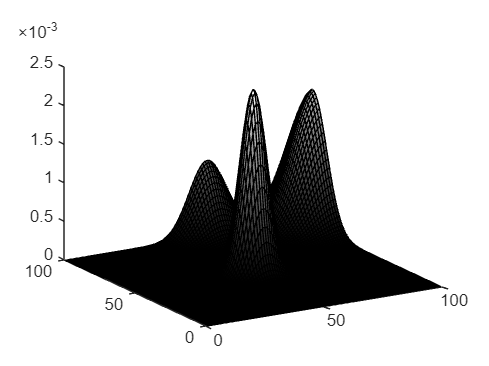

m=[50 50];
s=25*eye(2);
m2=[100 90];
s2=100*eye(2);
m3=[60 100];
s3=60*eye(2);

G1 = mvnpdf([X(:), Y(:)],m,s);
G2 = mvnpdf([X(:), Y(:)],m2,s2);
G3 = mvnpdf([X(:), Y(:)],m3,s3);
infoMap=(G1+3*G2+G3);

infoMap=max(infoMap,0); %crop below 0
infoMap=infoMap./max(infoMap); %normalize
infoMap = infoMap./sum(sum(infoMap));

Z = zeros(size(X));
opt.erg.mu=reshape(infoMap,size(X));

% figure(1);
% % set(gcf,'color','w'); 
% hold on
% surface(X,Y,Z,reshape(infoMap,size(X)), 'FaceColor','interp', 'EdgeColor','interp','Marker','.');
% colormap('gray');
% axis tight
% axis equal

figure(2); 
hold on
surf(X,Y,reshape(infoMap,size(X)));  % Bhaskar
colormap('gray');
view([-31.06163 21.91969])